clear all

CH_NUM = 40;
CH_SPAC = 100;

L = 12;

edfa_params_paper_1;

% 
% WL_ARRAY = 1518 + (1:CH_NUM) * 2 ;
% 
% FREQ_ARRAY = c./(WL_ARRAY * 10 ^ 12) * 10 ^ 9;

FREQ_ARRAY = 191.6 + (1:CH_NUM) * CH_SPAC * 10 ^ (-3);

WL_ARRAY = c./(FREQ_ARRAY * 10 ^ 12) * 10 ^ 9;

WL_ARRAY = fliplr(WL_ARRAY);

OBW = c ./ ((WL_ARRAY .* 10^(-9)).^2) * BW;

% EM_ARRAY = zeros(1,CH_NUM);
% AB_ARRAY = zeros(1,CH_NUM);
% 
% for k = 1:length(WL_ARRAY)
%     [EM_ARRAY(k),AB_ARRAY(k)] = get_EM_AB(WL_ARRAY(k),'EM_ERB_dost.csv','AB_ERB_dost.csv',25) ;
% end
% clear 'k'


% EM_ARRAY = zeros(1,CH_NUM);
% AB_ARRAY = zeros(1,CH_NUM);
% 
% [X_em , Y_em] = importfile('EM_BASIC_2.csv');
% [X_ab , Y_ab] = importfile('AB_BASIC_2.csv');
% 
% for k = 1:length(WL_ARRAY)
%     AB_ARRAY(k) = interp1(X_em,Y_em,WL_ARRAY(k),"linear") * 10^(-25);
%     EM_ARRAY(k) = interp1(X_ab,Y_ab,WL_ARRAY(k),"linear") * 10^(-25);
% end
% clear 'k'

EM_ARRAY = zeros(1,CH_NUM);
AB_ARRAY = zeros(1,CH_NUM);

for k = 1:length(WL_ARRAY)
    [EM_ARRAY(k),AB_ARRAY(k)] = get_EM_AB(WL_ARRAY(k),'EM_PAPER(1).csv','AB_PAPER(1).csv',0) ;
end
clear 'k'

T = 1*10^(-3);
span = [0 T];
y0 = 0;

%%%%%%%%%%%%%%%%%%%% Multi wavelength model %%%%%%%%%%%%%%%

P_p_dBm = 18; %dBm
P_s_in_0 = - 0; %dBm

P_p = 10 ^ (( P_p_dBm ) / 10) / 1000;

delta_P = 30;
N = 1;

P_s_in_ARRAY = zeros(1,N);
GAIN = zeros(N,CH_NUM);
N_sp = zeros(N,CH_NUM);
P_ASE = zeros(N,CH_NUM);
OSNR = zeros(N,CH_NUM);
P_s_dBm = zeros(1,N);


for g = 1:N  
    P_s_dBm(g) = P_s_in_0 + delta_P * (g-1);
    P_s_in_ARRAY = 10 .^ (( P_s_dBm ) ./ 10) ./ 1000;
end
clear 'g'

for g = 1:N
        
    [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L,EM_ARRAY,AB_ARRAY,WL_ARRAY,P_p,P_s_in_ARRAY(g),CH_NUM) ,span,y0);
       
       for u = 1:length(WL_ARRAY)
    
           GAIN(g,u) = exp(Gamma_s * (EM_ARRAY(u) + AB_ARRAY(u)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s * AB_ARRAY(u) * L / 4.3429);
           
           N_sp(g,u) = N2_m(length(t_m)) / ( N2_m(length(t_m)) - AB_ARRAY(u)/EM_ARRAY(u) * (rho*L*A - N2_m(length(t_m))));
           
           P_ASE(g,u) = 2 * h * c / (WL_ARRAY(u) * 10^(-9)) * N_sp(g,u) * OBW(u) * (GAIN(g,u) - 1);
           
           OSNR(g,u) = P_s_in_ARRAY(g) * GAIN(g,u)/P_ASE(g,u);
       end
end   
clear 'g' 'u'  


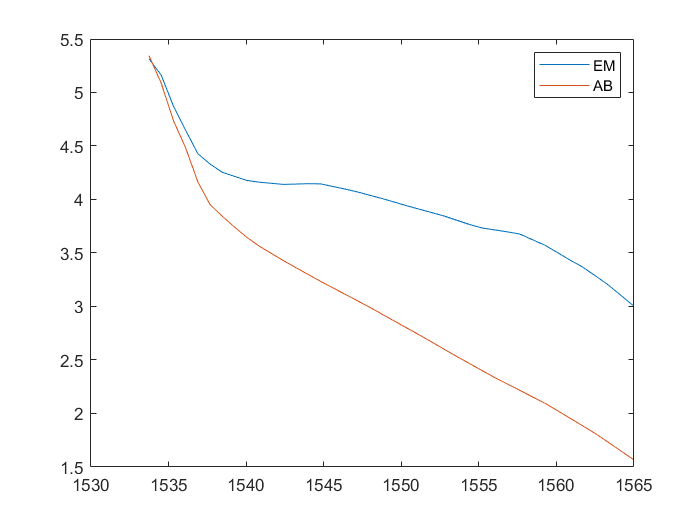


figure(1)
plot(WL_ARRAY,EM_ARRAY)
hold on
plot(WL_ARRAY,AB_ARRAY)
legend('EM' , 'AB')

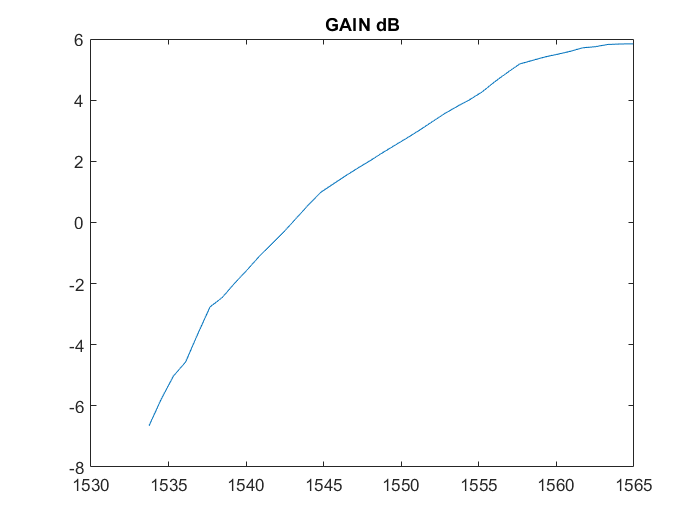


[WL_PAPER , GAIN_PAPER] = importfile('GAIN_PAPER.csv');

figure(2)
%plot(WL_PAPER,GAIN_PAPER);
%hold on
plot(WL_ARRAY,10*log10(GAIN))
%axis([1520 1570 18 38])
title('GAIN dB')

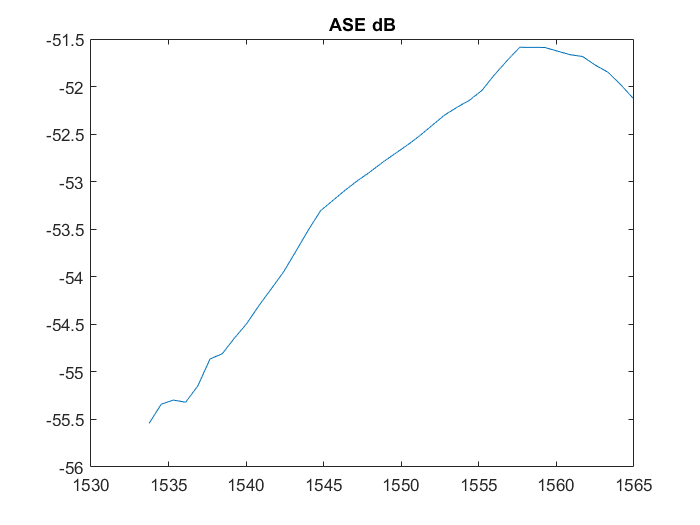

%legend('PAPER' , 'SIMULATED')

figure(3)
plot(WL_ARRAY,10*log10(P_ASE))
title('ASE dB')

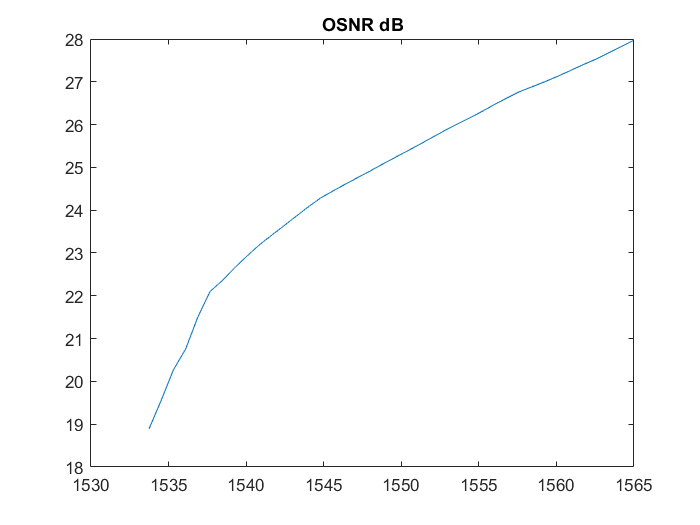


figure(4)
plot(WL_ARRAY,10*log10(OSNR))
title('OSNR dB')


clear 't_m' 'N2_m' 'g'

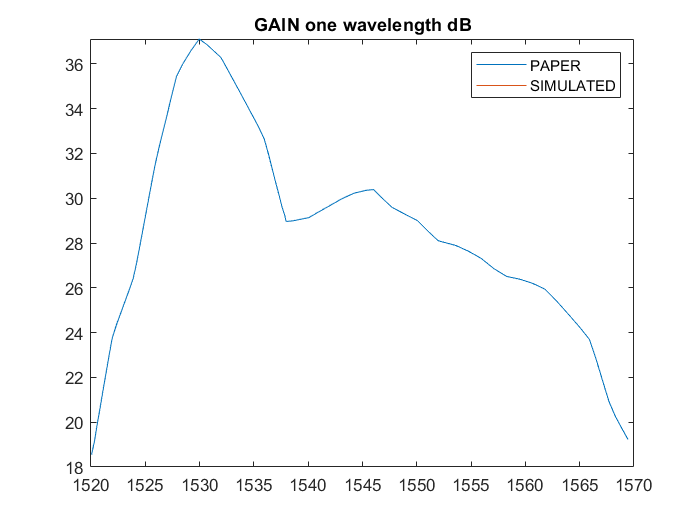

%%%%%%%%%%%%%%%%%%% one wavelength model %%%%%%%%%%%%%%%%%%%%

for g = 1:CH_NUM
        
    [t_m , N2_m] = ode15s(@(t_m,N2_m) edfa_eqs_paper_1(t_m,N2_m,L,EM_ARRAY(g),AB_ARRAY(g),WL_ARRAY(g),P_p,P_s_in_ARRAY(1),1) ,span,y0);
           
    GAIN_OW(g) = exp(Gamma_s * (EM_ARRAY(g) + AB_ARRAY(g)) / (4.3429 * rho * A) * N2_m(length(t_m)) - Gamma_s * AB_ARRAY(g) * L / 4.3429);
   
    N_sp_OW(g) = 1 / (1 - em_p * AB_ARRAY(g) / (ab_p * EM_ARRAY(g)));
   
    P_ASE_OW(g) = 2 * h * c / (WL_ARRAY(g) * 10^(-9)) * N_sp_OW(g) * OBW(g) * (GAIN_OW(g) - 1);
   
    OSNR_OW(g) = P_s_in_ARRAY(1) * GAIN_OW(g)/P_ASE_OW(g);
end   
clear 'g'  

figure(5)
plot(WL_PAPER,GAIN_PAPER);
hold on
plot(WL_ARRAY,10*log10(GAIN_OW))
axis([1520 1570 18 inf])
title('GAIN one wavelength dB')
legend('PAPER' , 'SIMULATED')

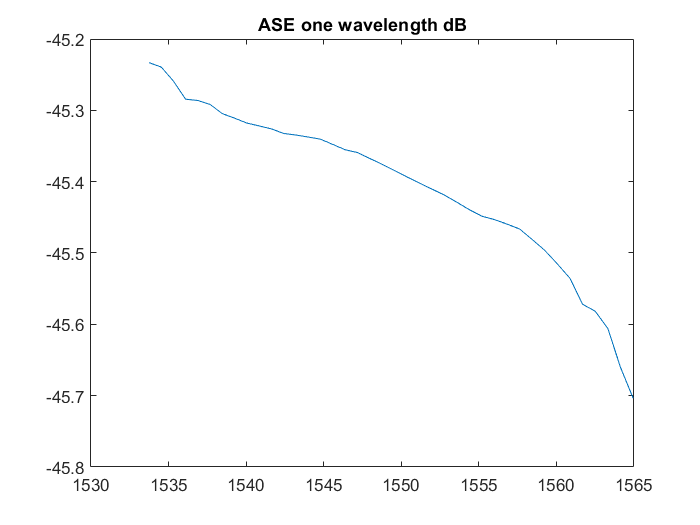


figure(6)
plot(WL_ARRAY,10*log10(P_ASE_OW))
title('ASE one wavelength dB')

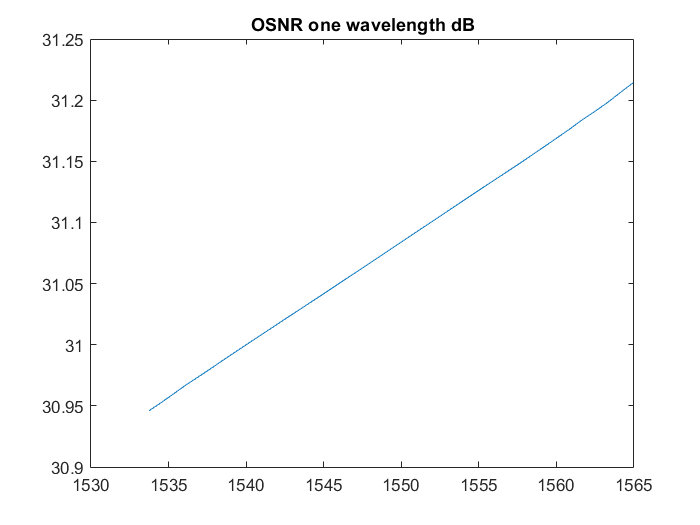


figure(7)
plot(WL_ARRAY,10*log10(OSNR_OW))
title('OSNR one wavelength dB')